# Function Handles and Zero-Finding

## Function Handles

A function handle is essentially a reference or pointer to a function. You can treat functions like variables and pass them around in your code.

Function handles are useful when you want to pass functions as inputs to other functions (algorithms). This is common in root-finding, numeric integration (solving differential equations), optimization, integration, and plotting.

Creation syntax:

f = @sin;  % Create a function handle for the sine function
result = f(pi/2)  % Use the handle to call the function

result = 1

### Plotting with Function Handles

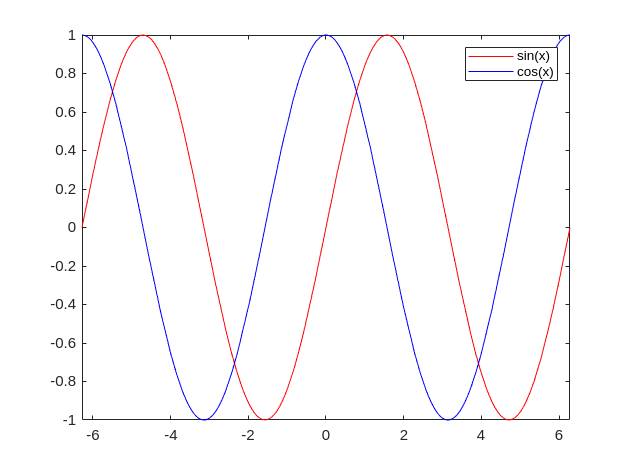

f1 = @sin;
f2 = @cos;

figure;
clf();
fplot(f1, [-2*pi, 2*pi], 'r');
hold on;
fplot(f2, [-2*pi, 2*pi], 'b');
hold off;

legend('sin(x)', 'cos(x)');

### * Exercises

Use a function handle to add a plot of the tangent function to the code above.

### Functions of Functions

Local function where the first argument is a function handle - just a variable.

function result = applyToRange(f, a, b)
    x = linspace(a, b, 100);
    % Call the user-specified function
    result = f(x);
end

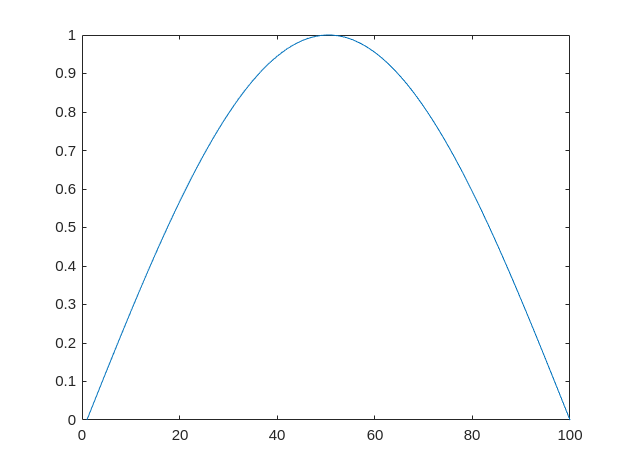

figure;
plot( applyToRange(@sin, 0, pi) )

## Algorithms

"Solver-based setup"

Separates what we want to do (the solver, or the algorithm) from what we want to do it to (the function handle).

The integral of a function is typically understood as the "`area under the curve`." In engineering and science, integrals are widely used for modeling, prediction, and analysis of physical systems. However, obtaining an exact solution for an integral is often challenging or even unachievable in practice. Therefore, we often use numerical methods that approximate the integral of a given function.

In a straightforward one-dimensional scenario, given a function f(x), we aim to approximate the integral of f(x) over the interval [a,b] using a finite sum approximation.A good illustration of the general problem of integration of a function in one dimension is given by the following [figure](https://pythonnumericalmethods.studentorg.berkeley.edu/notebooks/chapter21.01-Numerical-Integration-Problem-Statement.html):

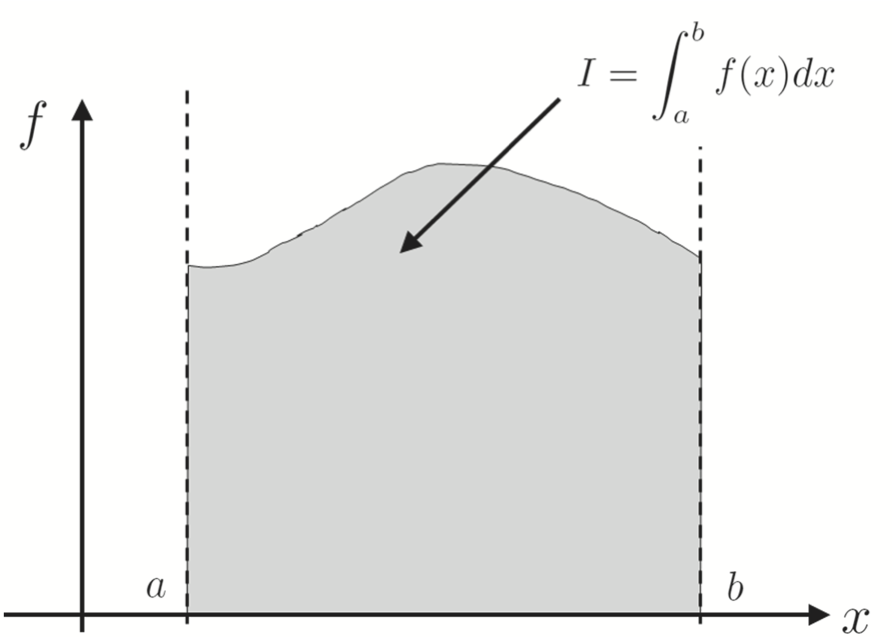

The `[`integral()`](https://www.mathworks.com/help/matlab/ref/integral.html)` function is used to numerically evaluate the integral of a function over a specified interval. This method is particularly useful for functions that cannot be integrated symbolically, or when an approximate numerical value is sufficient.

### Algorithm = Numerical Integration

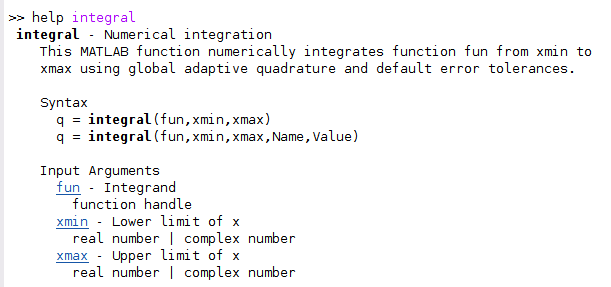

Find


$$\int_0^1 \text{e}^{x^2}dx$$


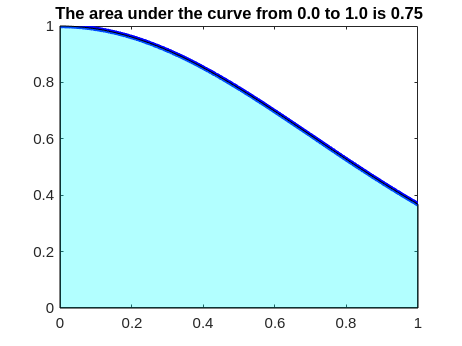

function y = expfun(x)
    y = exp(-x.^2);
end

figure
start = 0;
stop = 1;
areaunderthecurve = integral(@expfun, start, stop);

% Visualize
%fplot(@ifun, [start stop])
xx = linspace(start, stop, 100);
yy = expfun(xx);
plot(xx, yy, 'b', 'LineWidth', 3);
hold on;
fill([xx, fliplr(xx)], [zeros(size(xx)), fliplr(yy)], ...
    'cyan', 'FaceAlpha', 0.3);

title(sprintf("The area under the curve from %.1f to %.1f is %.2f", ...
    start, stop, areaunderthecurve))

### * Exercise

Use the `integral` function to estimate the solution to this definite integral:


$$\int_0^{2\pi}cos(\theta) \, d\theta$$


### Algorithm = Zero finding

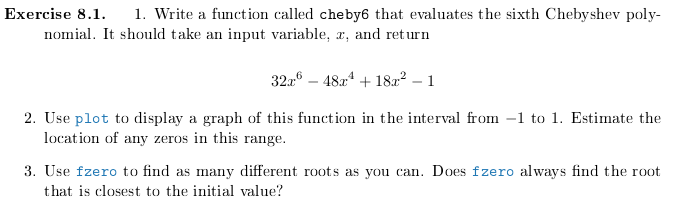

function res = cheby6(x)
    res = 32 .* x.^6 - 48 .* x.^4 + 18 .* x.^2 - 1;
end

Visualize the function

figure
clf
fplot(@cheby6, [-1 1])

Initial estimate

x0 = -1;

Apply the algorithm to our function.

root = fzero(@cheby6, x0);

Visualize the solution

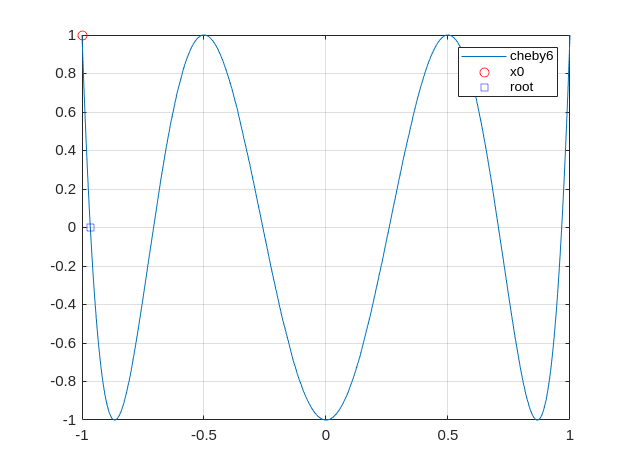

hold on;
plot(x0, cheby6(x0),"ro")
plot(root, cheby6(root), "bs")
legend("cheby6", "x0", "root")
grid('on')

#### Verbose output

Output as a structure:

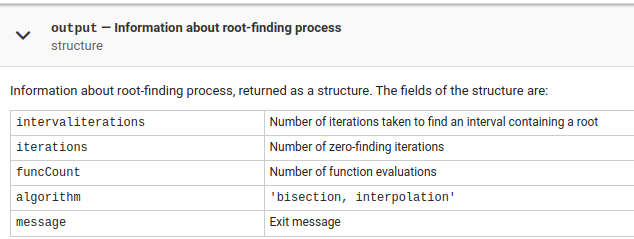

[x,fval,exitflag,output] = fzero(@cheby6, x0)

x = -0.9659

fval = -3.5527e-15

exitflag = 1

output = struct with fields:
    intervaliterations: 2
            iterations: 6
             funcCount: 10
             algorithm: 'bisection, interpolation'
               message: 'Zero found in the interval [-0.96, -1.02828]'


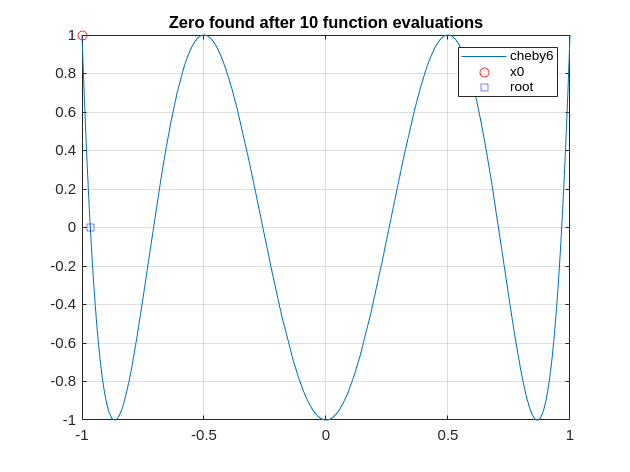

title(sprintf("Zero found after %d function evaluations", output.funcCount))

#### Options to control the algorithm

Algorithm options are set through a structure with lots of parameters:

options = optimset

options = struct with fields:
                   Display: []
               MaxFunEvals: []
                   MaxIter: []
                    TolFun: []
                      TolX: []
               FunValCheck: []
                 OutputFcn: []
                  PlotFcns: []
           ActiveConstrTol: []
                 Algorithm: []
    AlwaysHonorConstraints: []
           DerivativeCheck: []
               Diagnostics: []
             DiffMaxChange: []
             DiffMinChange: []
            FinDiffRelStep: []
               FinDiffType: []
         GoalsExactAchieve: []
                GradConstr: []
                   GradObj: []
                   HessFcn: []
                   Hessian: []
                  HessMult: []
               HessPattern: []
                HessUpdate: []
          InitBarrierParam: []
     InitTrustRegionRadius: []
                  Jacobian: []
                 JacobMult: []
              JacobPattern: []
                LargeScale: []
         

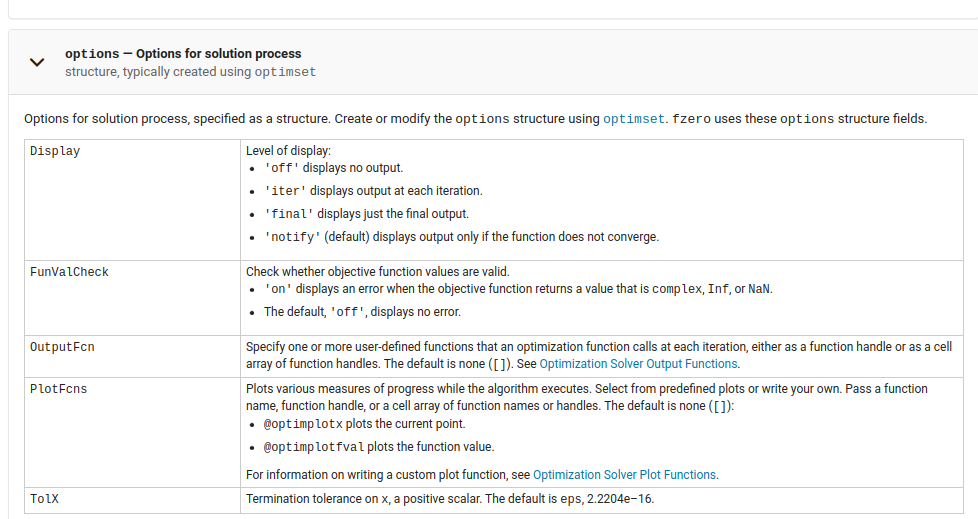

options.Display = 'iter';
root = fzero(@cheby6, x0, options)

 
Search for an interval around -1 containing a sign change:
 Func-count    a          f(a)             b          f(b)        Procedure
    1              -1             1            -1             1   initial interval
    3       -0.971716      0.139902      -1.02828       2.19665   search
    4           -0.96     -0.131586      -1.02828       2.19665   search
 
Search for a zero in the interval [-0.96, -1.02828]:
 Func-count    x          f(x)             Procedure
    4           -0.96     -0.131586        initial
    5       -0.963859    -0.0471977        interpolation
    6       -0.965972    0.00107749        interpolation
    7       -0.965925  -1.62079e-05        interpolation
    8       -0.965926  -5.42837e-09        interpolation
    9       -0.965926   7.10543e-15        interpolation
   10       -0.965926  -3.55271e-15        interpolation
 
Zero found in the interval [-0.96, -1.02828]


root = -0.9659

### * Exercise

Use built in plotting function handle `@optimplotfval` to visualize the progress of the `fzero` algoritm.

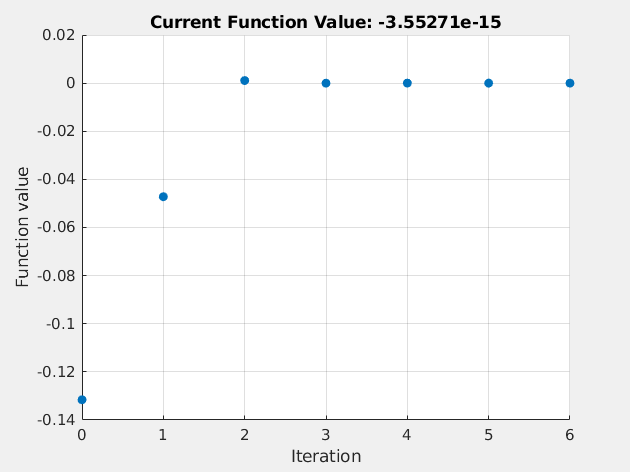

root = -0.9659